**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

**Q4 Determine the Bayes classification error rate for the data if the analysis is based on all of the available measurement features, where you will also need to apply proper data normalization. **

## Visualizing the feature data of each class

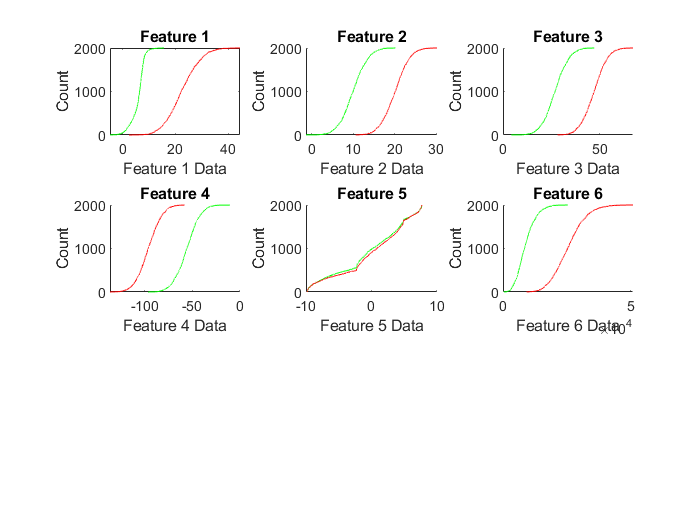

clear;
clc;
%rng(1)
% Load the Exercise 7 data set. 
load ('Exercise_7_Data.mat');

class_0 = find(class == 0);
class_1 = find(class == 1);

data_class_0 = data(class_0,:);
data_class_1 = data(class_1,:);


feature_data_class_0 = data_class_0(:,1);
feature_data_class_1 = data_class_1(:,1);
feature2_data_class_0 = data_class_0(:,2);
feature2_data_class_1 = data_class_1(:,2);
feature3_data_class_0 = data_class_0(:,3);
feature3_data_class_1 = data_class_1(:,3);
feature4_data_class_0 = data_class_0(:,4);
feature4_data_class_1 = data_class_1(:,4);
feature5_data_class_0 = data_class_0(:,5);
feature5_data_class_1 = data_class_1(:,5);
feature6_data_class_0 = data_class_0(:,6);
feature6_data_class_1 = data_class_1(:,6);


figure();
subplot(3, 3, 1)
plot(sort(feature_data_class_0), linspace(1, length(feature_data_class_0), 2000), 'green');
hold on;
plot(sort(feature_data_class_1), linspace(1, length(feature_data_class_1), 2000), 'red');
title('Feature 1');
xlabel('Feature 1 Data');
ylabel('Count');
hold off;


subplot(3, 3, 2)
hold on;
plot(sort(feature2_data_class_0), linspace(1, length(feature2_data_class_0), 2000), 'green');
plot(sort(feature2_data_class_1), linspace(1, length(feature2_data_class_1), 2000), 'red');
title('Feature 2');
xlabel('Feature 2 Data');
ylabel('Count');
hold off;


subplot(3, 3, 3)
hold on;
plot(sort(feature3_data_class_0), linspace(1, length(feature3_data_class_0), 2000), 'green');
plot(sort(feature3_data_class_1), linspace(1, length(feature3_data_class_1), 2000), 'red');
title('Feature 3');
xlabel('Feature 3 Data');
ylabel('Count');
hold off;

subplot(3, 3, 4)
hold on;
plot(sort(feature4_data_class_0), linspace(1, length(feature4_data_class_0), 2000), 'green');
plot(sort(feature4_data_class_1), linspace(1, length(feature4_data_class_1), 2000), 'red');
title('Feature 4');
xlabel('Feature 4 Data');
ylabel('Count');
hold off;


subplot(3, 3, 5)
hold on;
plot(sort(feature5_data_class_0), linspace(1, length(feature5_data_class_0), 2000), 'green');
plot(sort(feature5_data_class_1), linspace(1, length(feature5_data_class_1), 2000), 'red');
title('Feature 5');
xlabel('Feature 5 Data');
ylabel('Count');
hold off;


subplot(3, 3, 6)
hold on;
plot(sort(feature6_data_class_0), linspace(1, length(feature6_data_class_0), 2000), 'green');
plot(sort(feature6_data_class_1), linspace(1, length(feature6_data_class_1), 2000), 'red');
title('Feature 6');
xlabel('Feature 6 Data');
ylabel('Count');
hold off;

From the above plots we can see that the Features 1-4 have distribution in shape of a sigmoid function and hence, we tried using sigmoid transformation for normalizing these features. However, after experimenting with sigmoid, the plot of the features 1-4 were not having nice spread of the data. Hence, indicating the loss of information. Therefore, we tried another transformation technique, log base 10. The log base 10 transformation technique gives nice spread of the data and also, good classification performance. While, linear normalization technique has been used for feature 5 to normalize the range of feature 5 between (0,1) as the above plot indicates that the feature 5 is approximately linear. Feature 6 looks similar to a sigmoid function, however, there seems to be some loss of information after applying sigmoid and log transformation. Therefore, we have used linear transformation for feature 6 and observe very similar spreads of feature 6 before and after normalization indicating preservation of information.

## **Normalization**

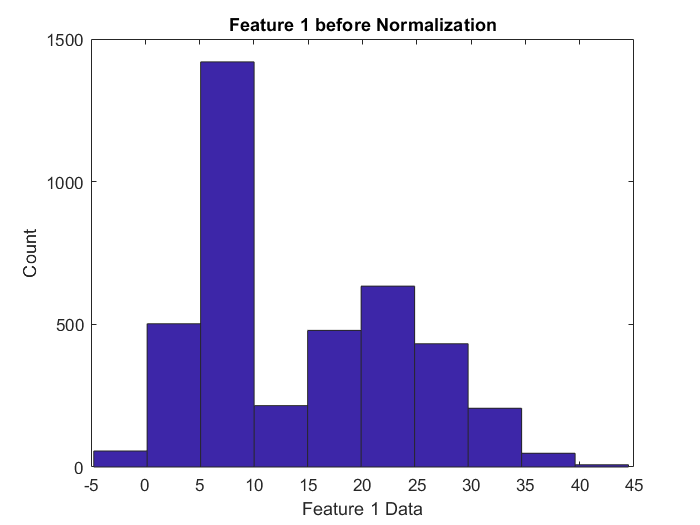

feature_data = data(:,1);
feature2_data = data(:,2);
feature3_data = data(:,3);
feature4_data = data(:,4);
feature5_data = data(:,5);
feature6_data = data(:,6);

figure();
hist(feature_data)
title('Feature 1 before Normalization');
xlabel('Feature 1 Data');
ylabel('Count');

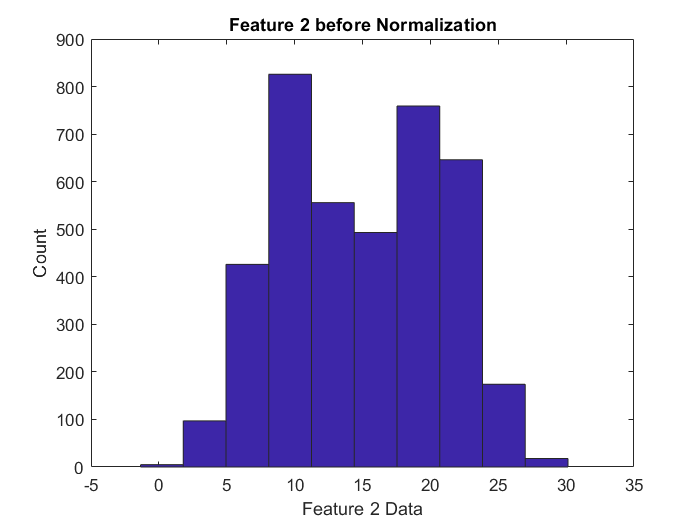



figure();
hist(feature2_data)
title('Feature 2 before Normalization');
xlabel('Feature 2 Data');
ylabel('Count');

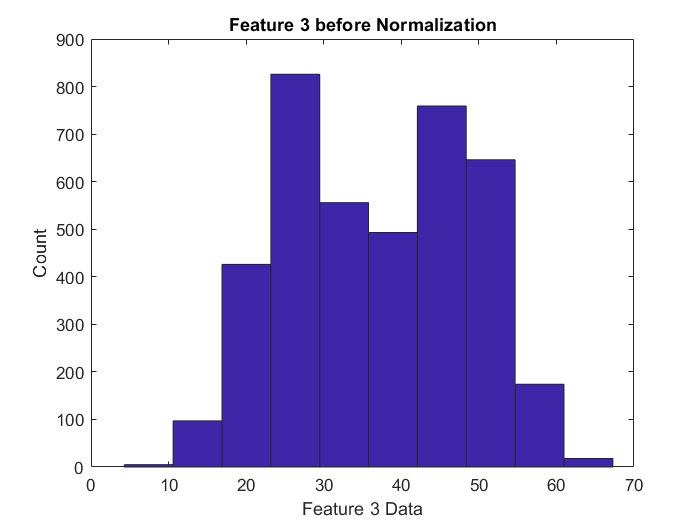

figure();
hist(feature3_data)
title('Feature 3 before Normalization');
xlabel('Feature 3 Data');
ylabel('Count');

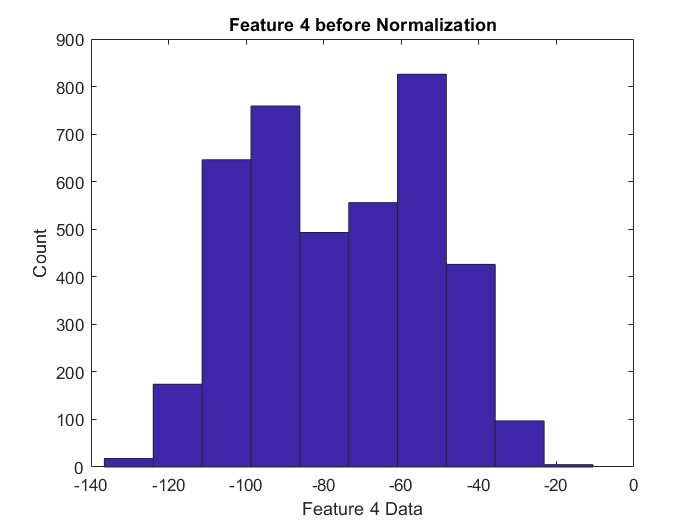

figure();
hist(feature4_data)
title('Feature 4 before Normalization');
xlabel('Feature 4 Data');
ylabel('Count');

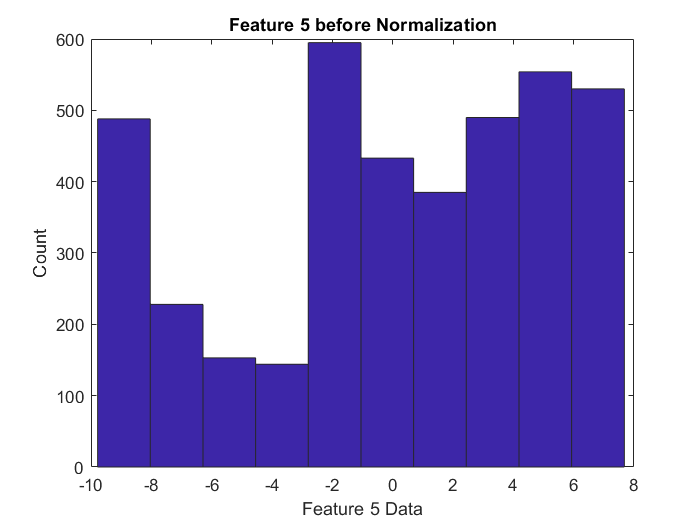

figure();
hist(feature5_data)
title('Feature 5 before Normalization');
xlabel('Feature 5 Data');
ylabel('Count');

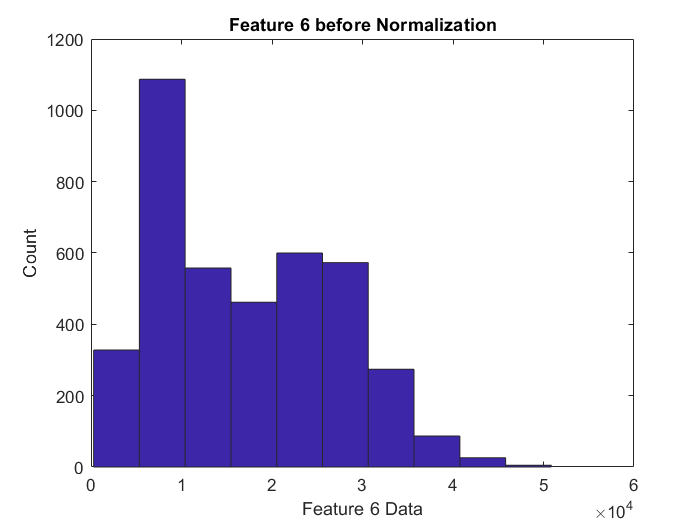

figure();
hist(feature6_data)
title('Feature 6 before Normalization');
xlabel('Feature 6 Data');
ylabel('Count');

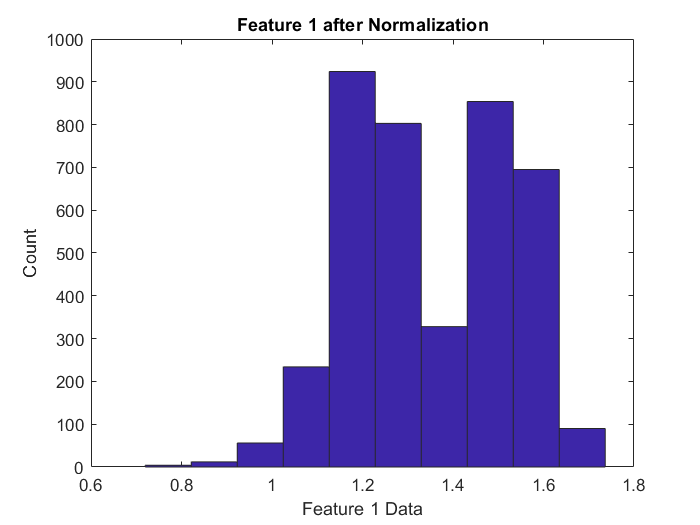


% added some scalars to plot the shifted data as otherwise it gives some error 
norm_feature_data = log10(data(:,1) + 10);
norm_feature2_data = log10(data(:,2));
norm_feature3_data = log10(data(:,3));
norm_feature4_data = log10(data(:,4) + 500);


% normalizing feature 5 in (0,1)
range_5_norm_0_1 = max(data(:,5))-min(data(:,5));
norm_feature5_data = (data(:,5) - min(data(:,5)))/range_5_norm_0_1;


range_6_norm_0_1 = max(data(:,6))-min(data(:,6));
feature_6_normalized_0_1 = (data(:,6) - min(data(:,6)))/range_6_norm_0_1;
%Normalize data in the range -1 to 1
norm_feature6_data = 2 * (feature_6_normalized_0_1) - 1;



figure();
hist(norm_feature_data)
title('Feature 1 after Normalization');
xlabel('Feature 1 Data');
ylabel('Count');

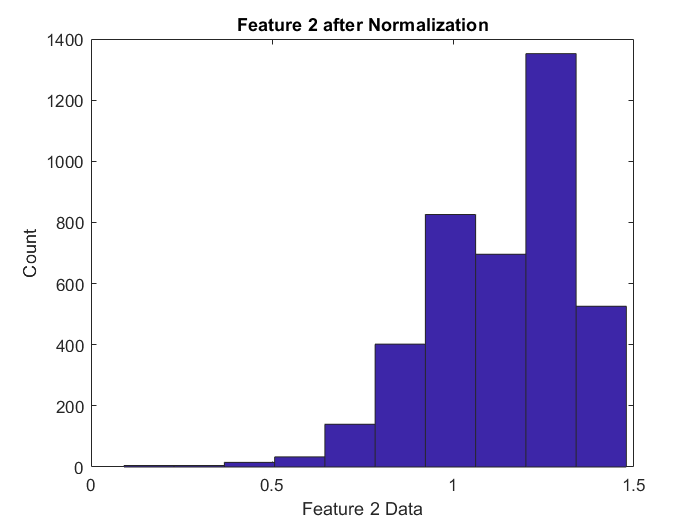



figure();
hist(norm_feature2_data)
title('Feature 2 after Normalization');
xlabel('Feature 2 Data');
ylabel('Count');

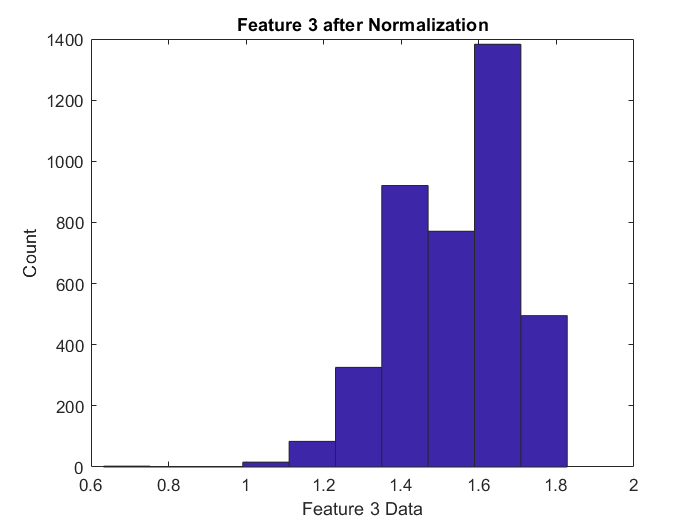


figure();
hist(norm_feature3_data)
title('Feature 3 after Normalization');
xlabel('Feature 3 Data');
ylabel('Count');

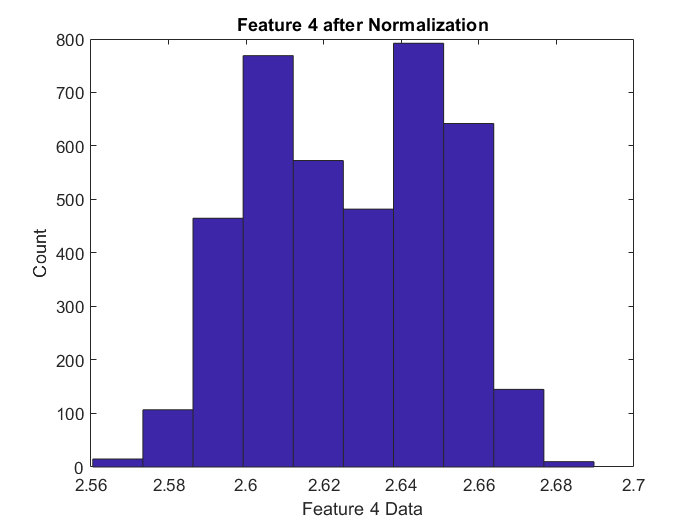


figure();
hist(norm_feature4_data)
title('Feature 4 after Normalization');
xlabel('Feature 4 Data');
ylabel('Count');

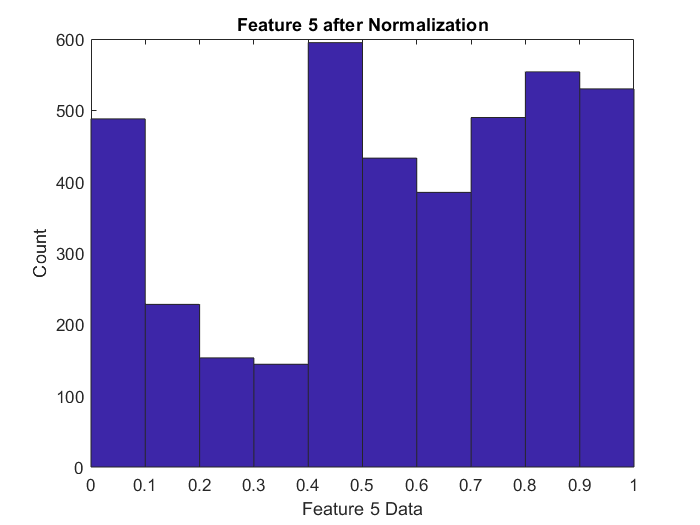


figure();
hist(norm_feature5_data)
title('Feature 5 after Normalization');
xlabel('Feature 5 Data');
ylabel('Count');

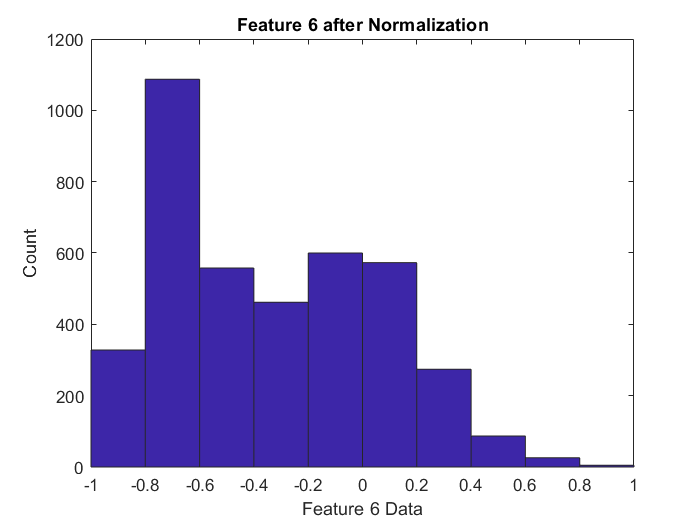


figure();
hist(norm_feature6_data)
title('Feature 6 after Normalization');
xlabel('Feature 6 Data');
ylabel('Count');

## Gaussian Mixture Model

% Normalized data
normalized_data = real([norm_feature_data norm_feature2_data norm_feature3_data norm_feature4_data norm_feature5_data norm_feature6_data]);
normalized_data_class_0 = normalized_data(class_0,:);
normalized_data_class_1 = normalized_data(class_1,:);

%Gaussian mixture model for class 0 data
AIC = zeros(1,10);
gm = cell(1,10);
options = statset('MaxIter', 500);

for k = 1:10
    gm{k} = fitgmdist(normalized_data_class_0,k,'Options', options, 'RegularizationValue', 0.2);
    AIC(k)= gm{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
bestmodel_0 = gm{numComponents};

%Gaussian mixture model for class 1 data
AIC = zeros(1,10);
gm = cell(1,10);
options = statset('MaxIter', 500);

for k = 1:10
    gm{k} = fitgmdist(normalized_data_class_1,k,'Options', options, 'RegularizationValue', 0.2);
    AIC(k)= gm{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
bestmodel_1 = gm{numComponents};


% PDF of the two classes
norm_data_class0_PDF = pdf(bestmodel_0, rand(10.^4, 6));
norm_data_class1_PDF = pdf(bestmodel_1, rand(10.^4, 6));

% Get the index for the misclassifications
region_error_0 = find(norm_data_class0_PDF < norm_data_class1_PDF);
region_error_1 = find(norm_data_class0_PDF > norm_data_class1_PDF);

% error of the two class data
error_0 = norm_data_class0_PDF(region_error_0, :);
error_1 = norm_data_class1_PDF(region_error_1, :);

% calculating the total error rate 
prior_prob_0 = length(class_0) / length(class);
prior_prob_1 = length(class_1) / length(class);
bayes_error_rate = prior_prob_0 * sum(error_0) / sum(norm_data_class0_PDF) + prior_prob_1 * sum(error_1) / sum(norm_data_class1_PDF) 

bayes_error_rate = 0.0275

**Q5 Determine the classification error for a neural network classifier trained on all of the available measurement features. Note, you will still need to properly partition the data into training and test sets.**

% splitting the data intto 70-30 train and test ratio
[data_for_training,data_for_testing,train_idx,test_idx] = train_validation_split(normalized_data);
label_training = class(train_idx);
label_testing = class(test_idx);

## Neural Network Classifier

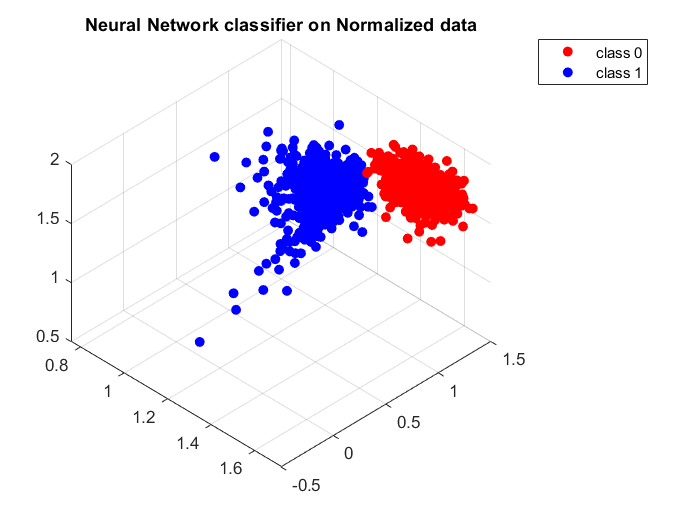

inputs = data_for_training';
targets = label_training;

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 85/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 0;

    
% Train the Network
[net,tr] = train(net,inputs,targets);
%Run the trained neural network with Testing data
outputs_test = net(data_for_testing');
region_1 = find(abs(outputs_test' - 1) < 0.5);
region_0 = find(abs(outputs_test' - 0) < 0.5);
matrix_1 = repmat([2], length(outputs_test), 1);
matrix_1(region_0, :) = 0; 
matrix_1(region_1, :) = 1;
result_label = matrix_1; 

% Array containing data points for each class
result_1 = data_for_testing(region_1, :);
result_2 = data_for_testing(region_0, :);

% Plot the classes 1, 2 regions
scatter3(result_1(:, 1), result_1(:, 2), result_1(:, 3), 'filled', 'red')
hold on;
scatter3(result_2(:, 1), result_2(:, 2), result_2(:, 3), 'filled', 'blue')
title('Neural Network classifier on Normalized data')
legend('class 0', 'class 1')
view([45, 45]);
hold off;


% Error percentage of Neural Network classifier
classification_issues = sum(result_label' ~= label_testing) *100 / length(label_testing)

classification_issues = 0.2500

**Q6 Compute the statistical correlation between each of the measurement features. Are these features statistically independent? **

**Ans. **We are using Pearson's Correlation Coefficient to compute the statistical correlation between the features. 

%Statistical Correlation can be found using the corr function in matlab
rof1_2 = corr(normalized_data(:,1),normalized_data(:,2))

rof1_2 = 0.7122

rof1_3 = corr(normalized_data(:,1),normalized_data(:,3))

rof1_3 = 0.7318

rof1_4 = corr(normalized_data(:,1),normalized_data(:,4))

rof1_4 = -0.7603

rof1_5 = corr(normalized_data(:,1),normalized_data(:,5))

rof1_5 = 0.0286

rof1_6 = corr(normalized_data(:,1),normalized_data(:,6))

rof1_6 = 0.7539


rof2_3 = corr(normalized_data(:,2),normalized_data(:,3))

rof2_3 = 0.9966

rof2_4 = corr(normalized_data(:,2),normalized_data(:,4))

rof2_4 = -0.9610

rof2_5 = corr(normalized_data(:,2),normalized_data(:,5))

rof2_5 = 0.0140

rof2_6 = corr(normalized_data(:,2),normalized_data(:,6))

rof2_6 = 0.9233


rof3_4 = corr(normalized_data(:,3),normalized_data(:,4))

rof3_4 = -0.9769

rof3_5 = corr(normalized_data(:,3),normalized_data(:,5))

rof3_5 = 0.0156

rof3_6 = corr(normalized_data(:,3),normalized_data(:,6))

rof3_6 = 0.9456


rof4_5 = corr(normalized_data(:,4),normalized_data(:,5))

rof4_5 = -0.0171

rof4_6 = corr(normalized_data(:,4),normalized_data(:,6))

rof4_6 = -0.9928


rof5_6 = corr(normalized_data(:,5),normalized_data(:,6))

rof5_6 = 0.0178

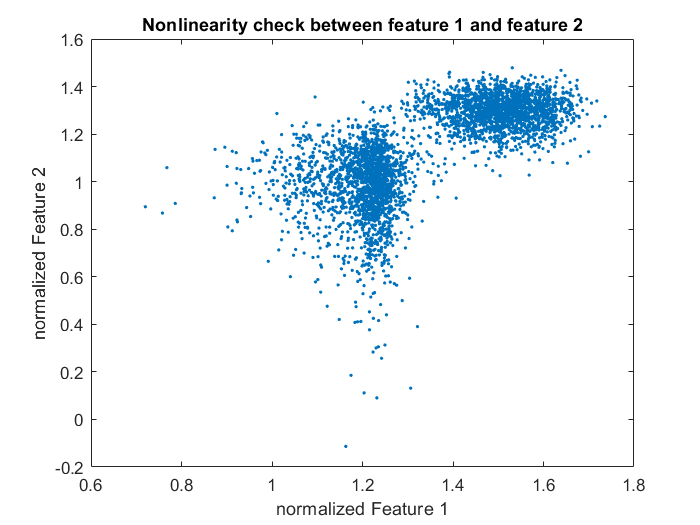


plot(normalized_data(:,1), normalized_data(:,2),'.')
hold on;
xlabel('normalized Feature 1');
ylabel('normalized Feature 2');
title('Nonlinearity check between feature 1 and feature 2')
hold off;

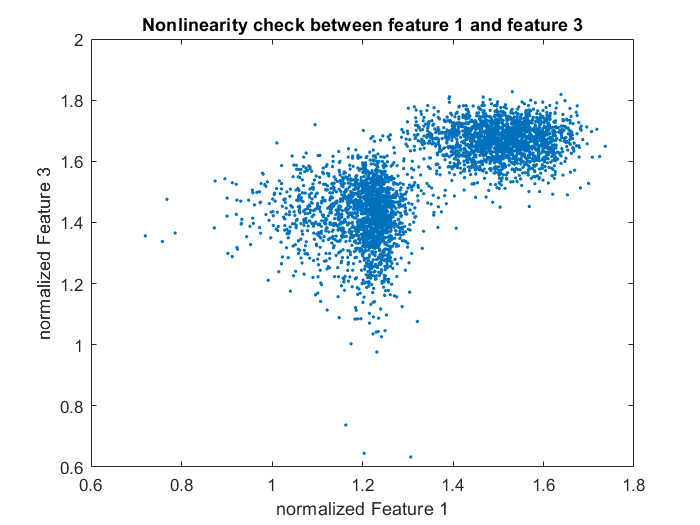

plot(normalized_data(:,1), normalized_data(:,3),'.')
hold on;
xlabel('normalized Feature 1');
ylabel('normalized Feature 3');
title('Nonlinearity check between feature 1 and feature 3')
hold off;

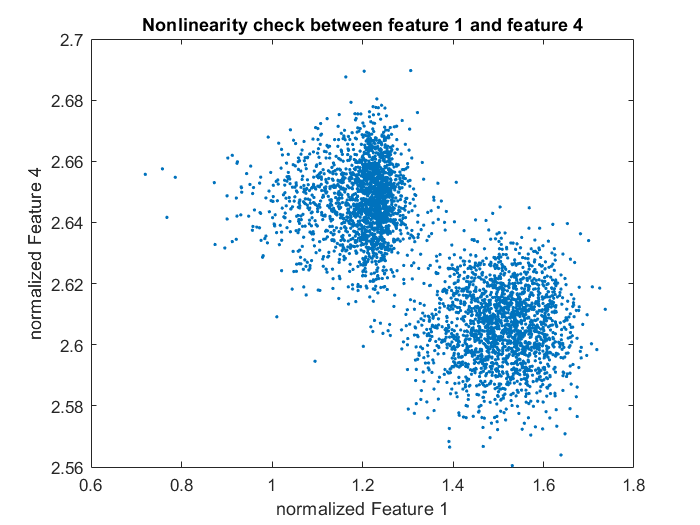


plot(normalized_data(:,1), normalized_data(:,4),'.')
hold on;
xlabel('normalized Feature 1');
ylabel('normalized Feature 4');
title('Nonlinearity check between feature 1 and feature 4')
hold off;

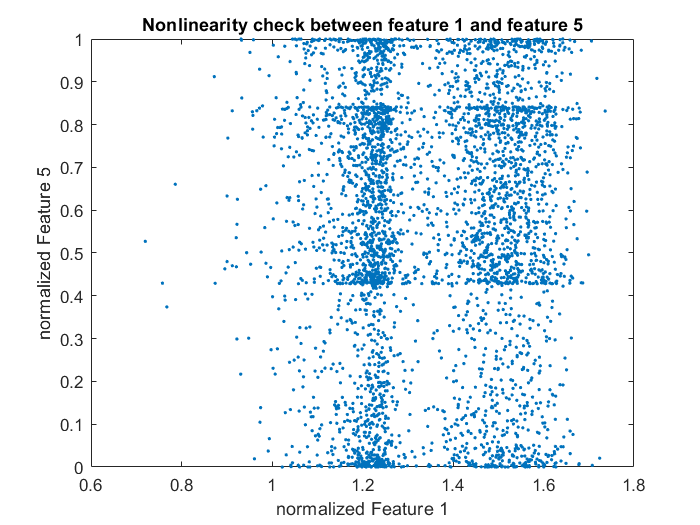


plot(normalized_data(:,1), normalized_data(:,5),'.')
hold on;
xlabel('normalized Feature 1');
ylabel('normalized Feature 5');
title('Nonlinearity check between feature 1 and feature 5')
hold off;

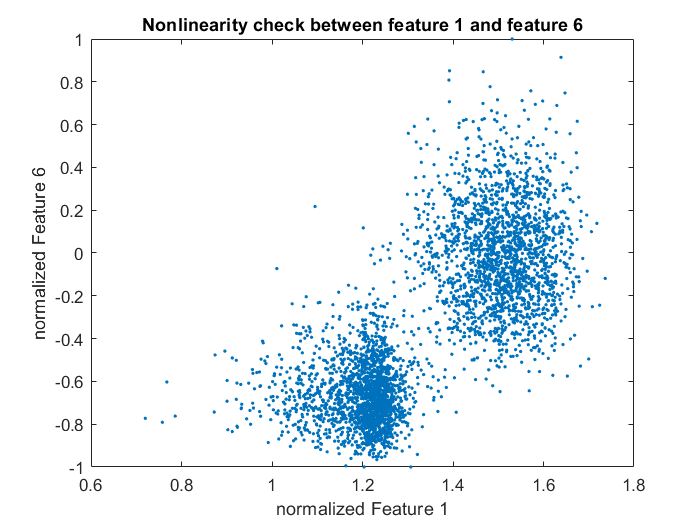


plot(normalized_data(:,1), normalized_data(:,6),'.')
hold on;
xlabel('normalized Feature 1');
ylabel('normalized Feature 6');
title('Nonlinearity check between feature 1 and feature 6')
hold off;

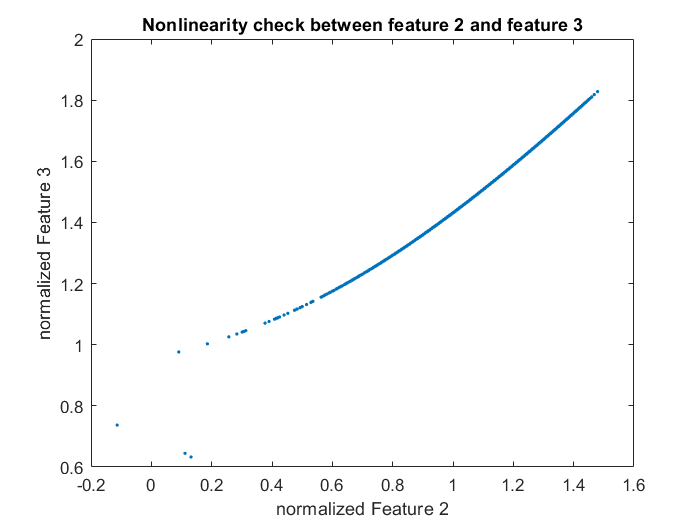


plot(normalized_data(:,2), normalized_data(:,3),'.')
hold on;
xlabel('normalized Feature 2');
ylabel('normalized Feature 3');
title('Nonlinearity check between feature 2 and feature 3')
hold off;

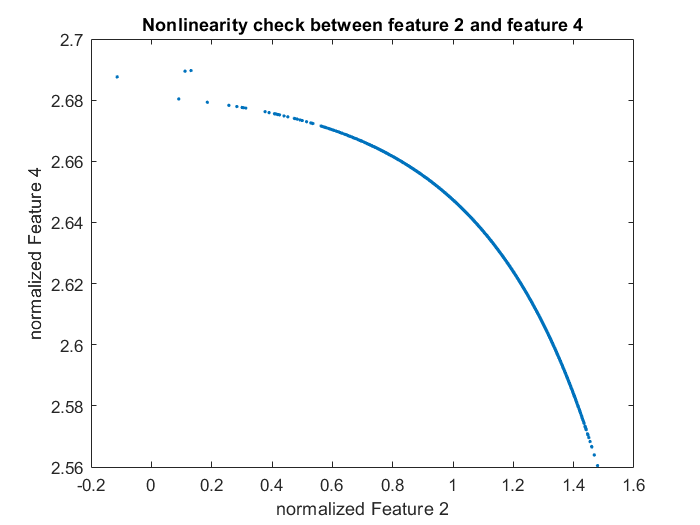


plot(normalized_data(:,2), normalized_data(:,4),'.')
hold on;
xlabel('normalized Feature 2');
ylabel('normalized Feature 4');
title('Nonlinearity check between feature 2 and feature 4')
hold off;

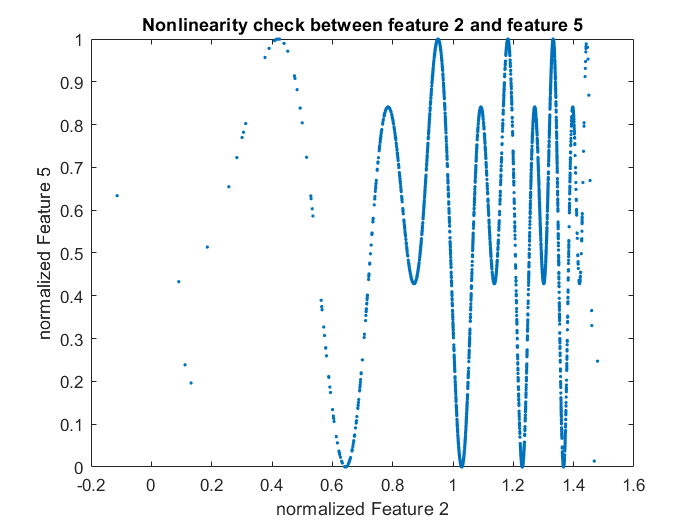


plot(normalized_data(:,2), normalized_data(:,5),'.')
hold on;
xlabel('normalized Feature 2');
ylabel('normalized Feature 5');
title('Nonlinearity check between feature 2 and feature 5')
hold off;

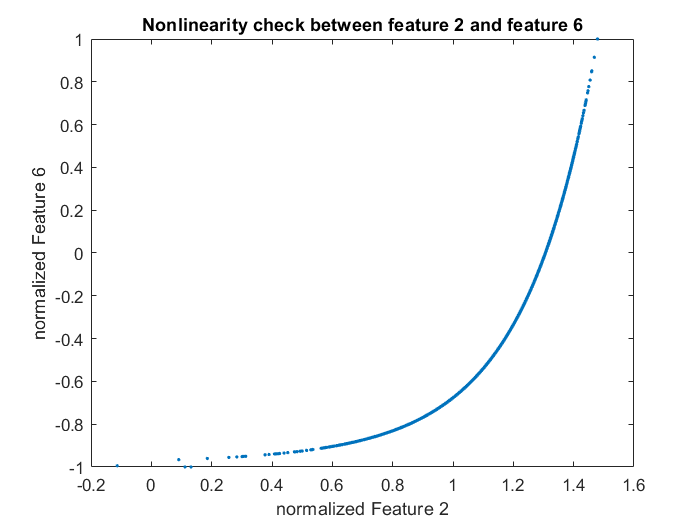


plot(normalized_data(:,2), normalized_data(:,6),'.')
hold on;
xlabel('normalized Feature 2');
ylabel('normalized Feature 6');
title('Nonlinearity check between feature 2 and feature 6')
hold off;

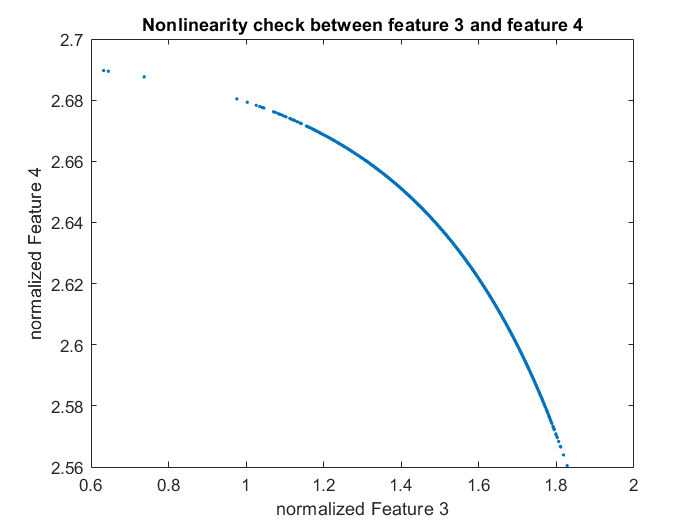


plot(normalized_data(:,3), normalized_data(:,4),'.')
hold on;
xlabel('normalized Feature 3');
ylabel('normalized Feature 4');
title('Nonlinearity check between feature 3 and feature 4')
hold off;

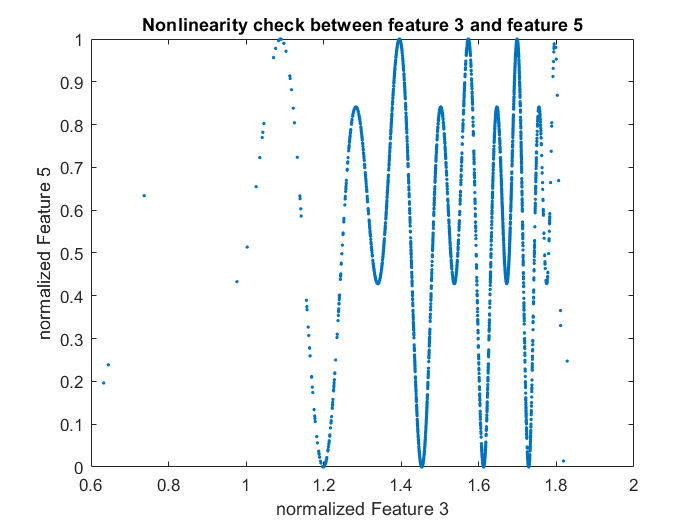


plot(normalized_data(:,3), normalized_data(:,5),'.')
hold on;
xlabel('normalized Feature 3');
ylabel('normalized Feature 5');
title('Nonlinearity check between feature 3 and feature 5')
hold off;

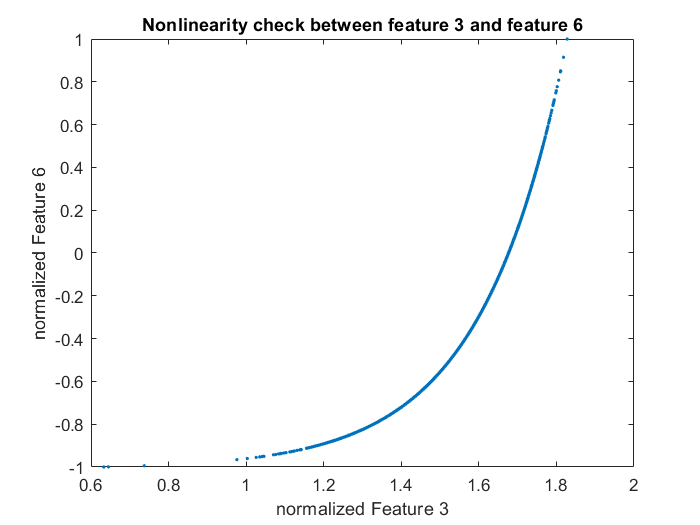


plot(normalized_data(:,3), normalized_data(:,6),'.')
hold on;
xlabel('normalized Feature 3');
ylabel('normalized Feature 6');
title('Nonlinearity check between feature 3 and feature 6')
hold off;

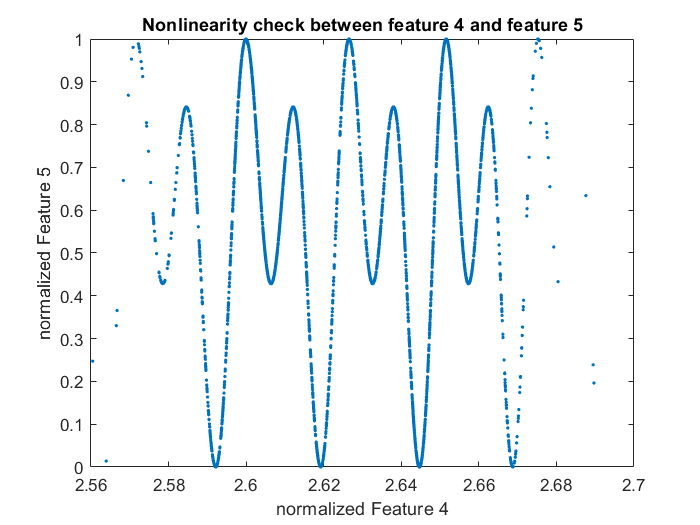


plot(normalized_data(:,4), normalized_data(:,5),'.')
hold on;
xlabel('normalized Feature 4');
ylabel('normalized Feature 5');
title('Nonlinearity check between feature 4 and feature 5')
hold off;

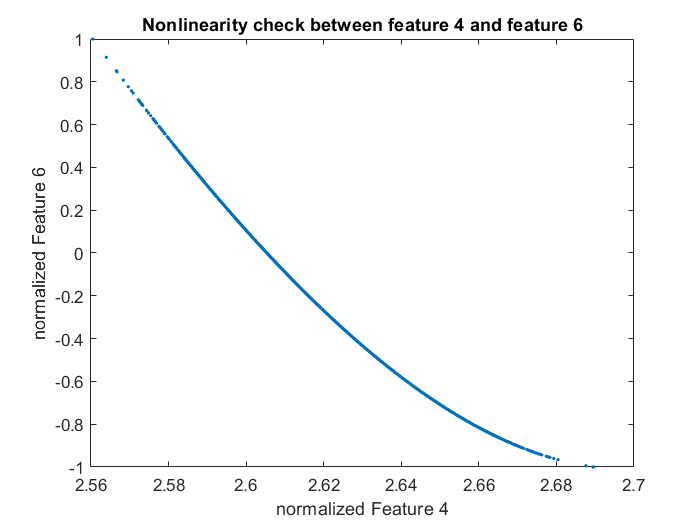


plot(normalized_data(:,4), normalized_data(:,6),'.')
hold on;
xlabel('normalized Feature 4');
ylabel('normalized Feature 6');
title('Nonlinearity check between feature 4 and feature 6')
hold off;

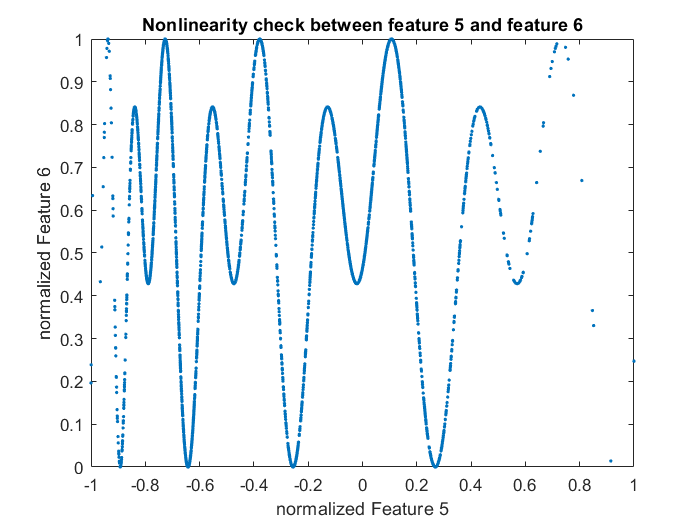


plot(normalized_data(:,6), normalized_data(:,5),'.')
hold on;
xlabel('normalized Feature 5');
ylabel('normalized Feature 6');
title('Nonlinearity check between feature 5 and feature 6')
hold off;

**Ans :** Pearson's Correlation Coefficient is used to find the strength of linear relation between two features. If the coefficient value is 0, it indicates that there is non linear or no relation between the data and if the coefficient value is -1 or 1, it indicates that there is a full negative or positive linear correlation respectively between the data.

Comparing the coefficient value of the different combinations of measurement features, we can see that corr1_2, corr1_3, corr1_6, corr2_6, corr2_3, corr3_6 are close to 1 which indicates that there is strong positive linear correlation between the features of these pairs and corr1_4, corr4_6 ,corr2_4 , corr3_4 are close to -1 which indicates strong negative linear correlation. Therefore, suggesting that these features are not statistically independent.

The rest of them (corr1_5, corr2_5, corr4_5, corr5_6, corr3_5, corr2_6) are close to 0 indicating that these features do not have linear correlation.

Looking at the scatter plots of these combination of measurement features, we can see that for combinations (4,6), (3,6), (3,4), (2,6),(2,4),(2,3), there is a linear relationship and are not statistically independent. For all the other feature combinations except for (1, 2), (1, 3), (1, 4), (1, 5), (1, 6), we can see that there is a sinosoidal relation between the data which indicates that these feature data are not statistically independent as even if there is non linear correlation, there is non linear relation and dependence. Features (1, 2), (1, 3), (1, 4), (1, 5), (1, 6) are statistically independent as there is neither linear nor non-linear relation between each of the feature pairs.

function [training_data,validation_data,train_idx,test_idx] = train_validation_split(dataset)
    training_ratio = 0.70;
    dataset_size = length(dataset);
    idx = randperm(dataset_size);
    split = floor(training_ratio * dataset_size);
    train_idx = idx(1:split);
    test_idx = idx(split+1: end);
    training_data = dataset(train_idx,:);
    validation_data = dataset(test_idx,:);
    
end 